clear; close all; clc;

# Cart and Pendulum Simulation

**Authors: **B. Carbonneau, B. Kwan, D. Riccoboni, Z. Richter

**Last Modified: **May 26, 2021

**Description: ** The following script will control the cart pdenulum system using two different control strategies. The first control strategy will be using LQR. The second will involve genetic programming to determine the best gains for the system. 

**Necessary Files:** `cartpend.mlx ` ------- Function file holding the equations of motion for the cart/pendulum system. 

## Defining system parameters

m = 2;        % Pendulum bob mass [kg]
M = 10;       % Cart mass [kg]
g = 9.81;     % gravitational acceleration [m/s/s]
L = .66;      % Pendulum length [m]

## Running the Simulation

#### Define Initial Conditions

The following lines of code will define the initial conditions for the simulation

x_cart = 0;
x_dot_cart =0;
ang = pi/10;
ang_dot = 0;
int_theta = 0;
int_x = 0;
ICs = [x_cart, x_dot_cart, ang, ang_dot, int_theta, int_x];

Next, define the time span for the simulation

tfinal = 10;
tspan = 0:.01:tfinal;

Finally, the simulation of the system can be run.

[t,y] = ode45(@(t,y)cartpend(t,y,m,M,L,g,@(x)0),tspan,ICs);

#### Plotting the open loop simulation results

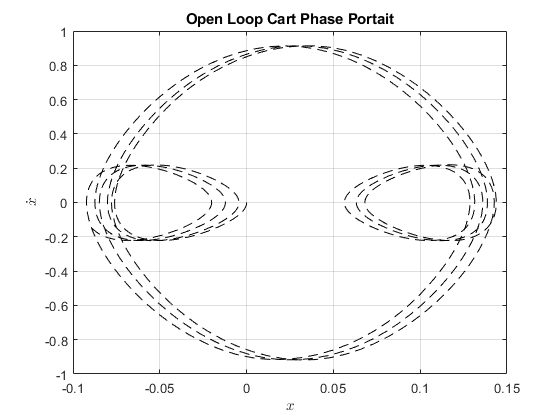

cartResponseOL = figure;
cartResponseOL.Color = 'white'; cartResponseOL.Visible = 'on';
plot(y(:,1),y(:,2),'k--')
grid on; box on;
xlabel('$x$','Interpreter','latex'); ylabel('$\dot{x}$','Interpreter',"latex");
title('Open Loop Cart Phase Portait')

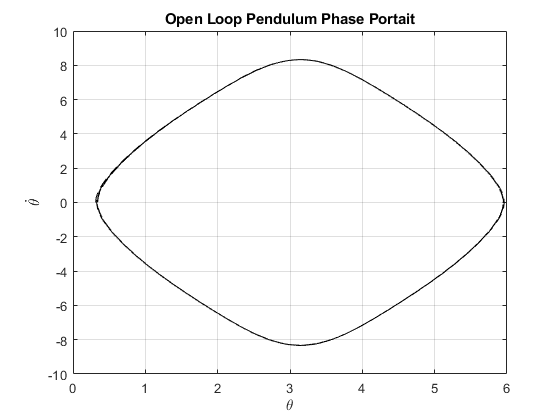

pendResponseOL = figure;
pendResponseOL.Color = 'white'; pendResponseOL.Visible = 'on';
plot(y(:,3),y(:,4),'k--')
grid on; box on;
xlabel('$\theta$','Interpreter','latex'); ylabel('$\dot{\theta}$','Interpreter',"latex");
title('Open Loop Pendulum Phase Portait')

Both of these phase portraits show the instability in the system. The angle changes indefinitiely and the cart also has oscilatory behavior as the pendulum swings. 

## Set up LQR Controller

from linearized model found in Problem Set 1

A = [0,1,0,0;
    0,0,(-g*m)/M,0;
    0,0,0,1;
    0,0,g*(M+m)/M/L,0;
    0, 0, 1, 0, 0;
    1, 0, 0, 0, 0];
B = [0; 1/M; 0; -1/M/L; 0; 0];
C = [0 0 1 0 0 0]; 
D = 0; 

disp(eigs(A)) %unstable 

    4.2233
   -4.2233
         0
         0



The eigen values of the linearized dynamics are the open loop poles, and since there is a positive real value, the systems dynamics are unstable. 

First stabilize the system, so that the `lqr `function can be utilized.

desired_poles = [-1, -0.9, -1+0.1*j,-1-0.1*j, -1.1, -0.8];
K = place(A,B,desired_poles);

Creat Q and R values for LQR control gain. These values are chosen such that stabilizing the pendulum in the upright position is the highest priority, followed by bringing the cart back to the origin. 

pen = [5 3 8 2 1 1.5];  Q = diag(pen); 
R = 0.10; 
[K_lqr, P]= lqr(A-B*K,B,Q,R);

The total system is depended on both of the feedback gains, which are in nested loops within the system

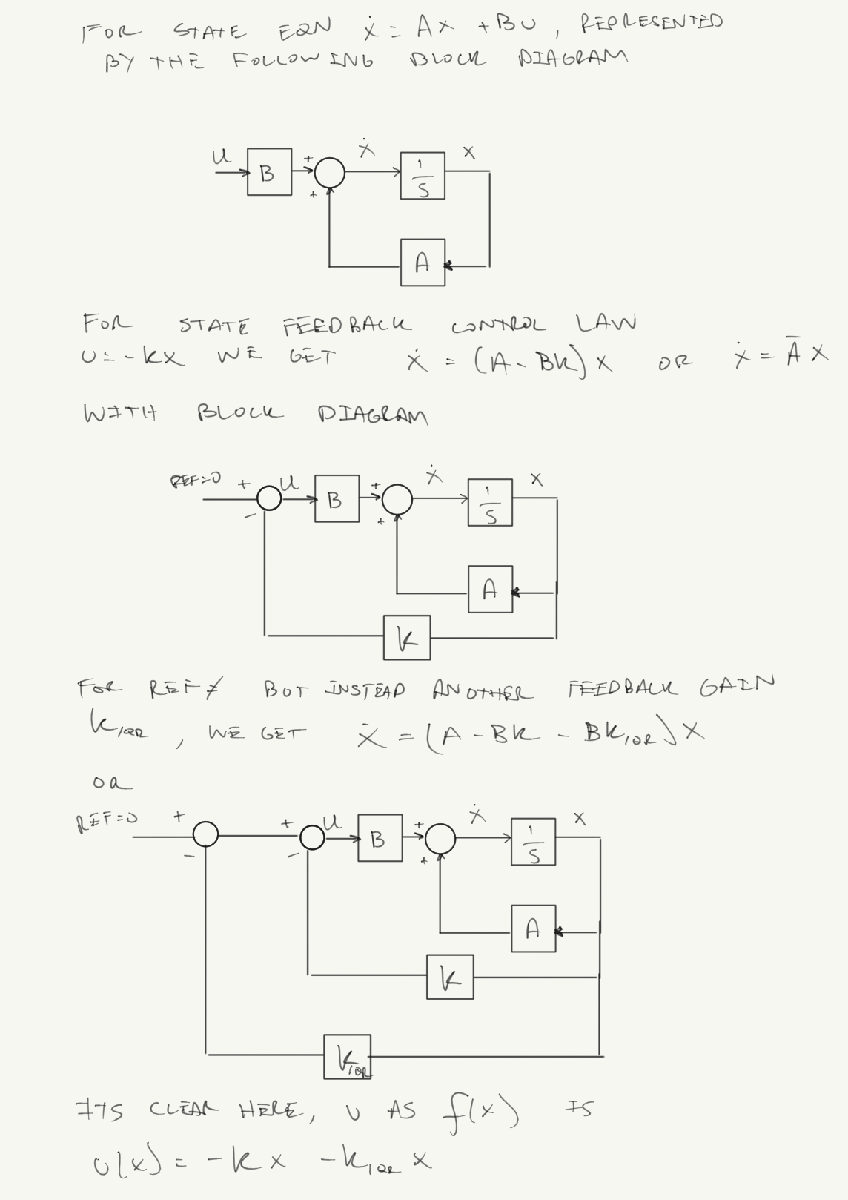

[y,t,x] = initial(ss(A-B*K - B*K_lqr,B,C,D),ICs,tspan(end));
u_lqr = @(x) -K*x - K_lqr*x;
sys_lqr = @(t,x)cartpend(t,x,m,M,L,g,u_lqr);
[tnl,xnl] = ode45(sys_lqr,tspan,ICs);

Plot time response of LQR controlled system

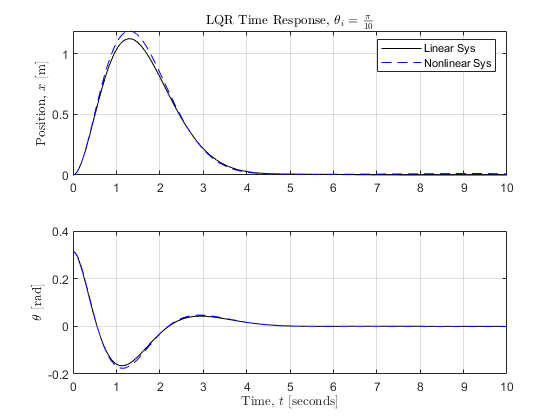

ResponseLQR = figure;
ResponseLQR.Color = 'white'; ResponseLQR.Visible = 'on';
subplot(2,1,1)
hold on
plot(t,x(:,1),'k')
plot(tnl,xnl(:,1),'--b')
grid on; box on; hold off
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('LQR Time Response, $\theta_i = \frac{\pi}{10}$','Interpreter',"latex")
legend('Linear Sys','Nonlinear Sys')
subplot(2,1,2)
hold on
plot(t,x(:,3),'k')
plot(tnl,xnl(:,3),'--b')
grid on; box on; hold off
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");

For this small inital angle, the linear and nonlinear systems behave similarly when the two feedback gains are determining the required control input. 

## Genetic Programming

This section uses the result from our genetic programming script

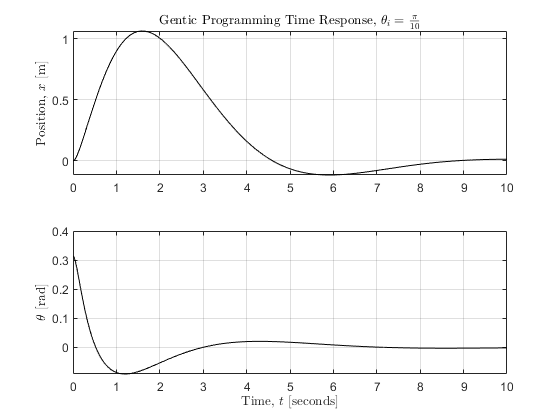

load("cont1.mat");
tspan = [0 10];
sys_gp = @(t,x)cartpend(t,x,m,M,L,g,bestFcn);
[t1,x1] = ode45(sys_gp,tspan,ICs);

ResponseGP = figure;
ResponseGP.Color = 'white'; ResponseGP.Visible = 'on';
subplot(2,1,1)
plot(t1,x1(:,1),'k')
grid on; box on;
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('Gentic Programming Time Response, $\theta_i = \frac{\pi}{10}$','Interpreter',"latex")
subplot(2,1,2)
plot(t1,x1(:,3),'k')
grid on; box on;
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");

The control law from the genetic programming method also shows the stable behavior desired from this controller. An the function tree for this controller is shown below.  

disp(bestTree.tostring)

                                 plus                                  
          +-----------------------+-----------+                        
          |                                   |                        
        plus                                plus                       
     +----+-----+          +-----------------+-----+                   
     |          |          |                       |                   
   times      times      times                   plus                  
  +-+---+    +-+---+    +-+---+       +------------+-----+             
  |     |    |     |    |     |       |                  |             
x(3)   500 x(4)   75  x(4)   75     times              plus            
                                   +-+---+       +------+-----+        
                                   |     |       |            |        
                                 x(1)   10     times        times      
                                              +-+---+    +----+-

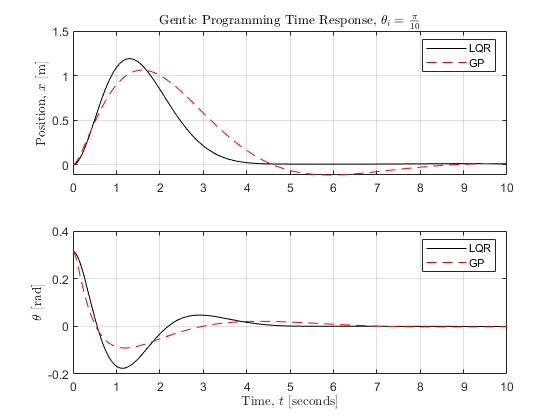

ResponsePi10 = figure;
ResponsePi10.Color = 'white'; ResponsePi10.Visible = 'on';
subplot(2,1,1)
hold on
plot(tnl,xnl(:,1),'k')
plot(t1,x1(:,1),'--r')
grid on; box on; hold off;
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('Gentic Programming Time Response, $\theta_i = \frac{\pi}{10}$','Interpreter',"latex")
legend('LQR','GP')
subplot(2,1,2)
hold on
plot(tnl,xnl(:,3),'k')
plot(t1,x1(:,3),'--r')
grid on; box on; hold off
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");
legend('LQR','GP')

Overlaying the LQR and gentic programming method shows interesting behavior as the LQR method has a faster settling time but larger overshoot for the carts position, and very similar settling times but again larger overshoot for the pendulum angle. 

%determine cost of each of these controllers
uvals_lqr = zeros(length(tnl),1);
for n = 1:length(tnl)
    uvals_lqr(n) = u_lqr(xnl(n,:)');
end
cost_lqr = costCalc(tnl,xnl,uvals_lqr,Q,R)

cost_lqr = 152.9674


uvals_gp = zeros(length(t1),1);
for n = 1:length(t1)
    uvals_gp(n) = u_lqr(x1(n,:)');
end
cost_gp = costCalc(t1,x1,uvals_gp,Q,R)

cost_gp = 58.0736

From how the cost function is defined with the values of Q and R, the genetic programming method produces a response with a lower cost 

Now test controllers for increasing initial displacements

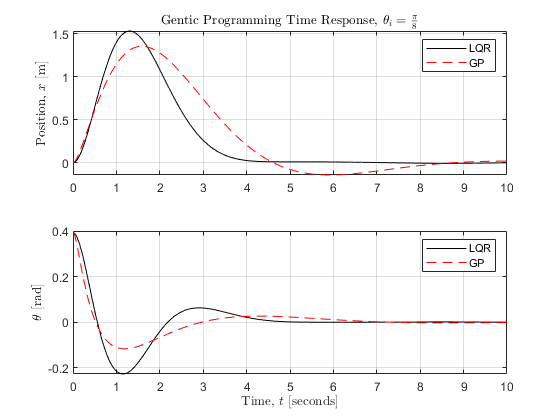

x_cart = 0;
x_dot_cart =0;
ang = pi/8;
ang_dot = 0;
ICs = [x_cart, x_dot_cart, ang, ang_dot, int_theta, int_x];
[t,x] = ode45(sys_lqr,tspan,ICs);
[t1,x1] = ode45(sys_gp,tspan,ICs);

ResponsePi8 = figure;
ResponsePi8.Color = 'white'; ResponsePi8.Visible = 'on';
subplot(2,1,1)
hold on
plot(t,x(:,1),'k')
plot(t1,x1(:,1),'--r')
grid on; box on; hold off;
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('Gentic Programming Time Response, $\theta_i = \frac{\pi}{8}$','Interpreter',"latex")
legend('LQR','GP')
subplot(2,1,2)
hold on
plot(t,x(:,3),'k')
plot(t1,x1(:,3),'--r')
grid on; box on;
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");
legend('LQR','GP')

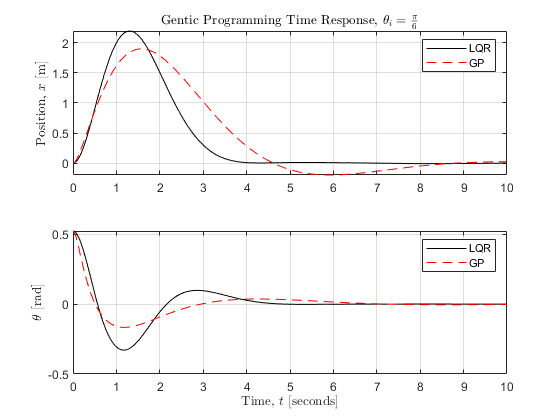

x_cart = 0;
x_dot_cart =0;
ang = pi/6;
ang_dot = 0;
ICs = [x_cart, x_dot_cart, ang, ang_dot, int_theta, int_x];
[t,x] = ode45(sys_lqr,tspan,ICs);
[t1,x1] = ode45(sys_gp,tspan,ICs);

ResponsePi6 = figure;
ResponsePi6.Color = 'white'; ResponsePi6.Visible = 'on';
subplot(2,1,1)
hold on
plot(t,x(:,1),'k')
plot(t1,x1(:,1),'--r')
grid on; box on; hold off;
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('Gentic Programming Time Response, $\theta_i = \frac{\pi}{6}$','Interpreter',"latex")
legend('LQR','GP')
subplot(2,1,2)
hold on
plot(t,x(:,3),'k')
plot(t1,x1(:,3),'--r')
grid on; box on;
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");
legend('LQR','GP')

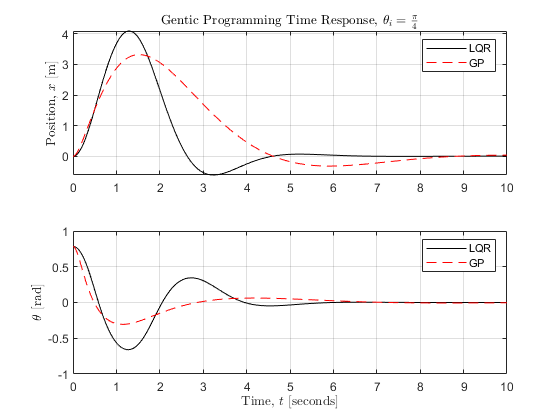

x_cart = 0;
x_dot_cart =0;
ang = pi/4;
ang_dot = 0;
ICs = [x_cart, x_dot_cart, ang, ang_dot, int_theta, int_x];
[t,x] = ode45(sys_lqr,tspan,ICs);
[t1,x1] = ode45(sys_gp,tspan,ICs);

ResponsePi4 = figure;
ResponsePi4.Color = 'white'; ResponsePi4.Visible = 'on';
subplot(2,1,1)
hold on
plot(t,x(:,1),'k')
plot(t1,x1(:,1),'--r')
grid on; box on; hold off;
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('Gentic Programming Time Response, $\theta_i = \frac{\pi}{4}$','Interpreter',"latex")
legend('LQR','GP')
subplot(2,1,2)
hold on
plot(t,x(:,3),'k')
plot(t1,x1(:,3),'--r')
grid on; box on;
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");
legend('LQR','GP')

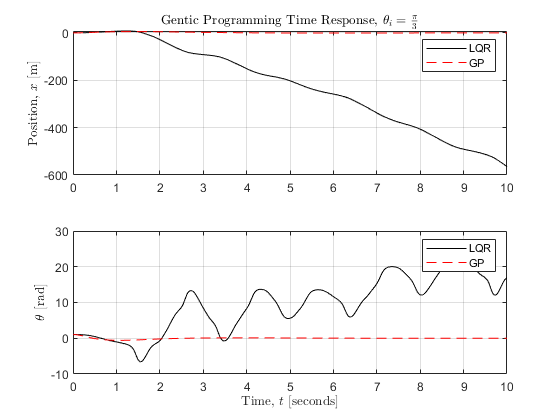

x_cart = 0;
x_dot_cart =0;
ang = pi/3;
ang_dot = 0;
ICs = [x_cart, x_dot_cart, ang, ang_dot, int_theta, int_x];
[t,x] = ode45(sys_lqr,tspan,ICs);
[t1,x1] = ode45(sys_gp,tspan,ICs);

ResponsePi2 = figure;
ResponsePi2.Color = 'white'; ResponsePi2.Visible = 'on';
subplot(2,1,1)
hold on
plot(t,x(:,1),'k')
plot(t1,x1(:,1),'--r')
grid on; box on; hold off;
ylabel('Position, $x$ [m]','Interpreter',"latex");
title('Gentic Programming Time Response, $\theta_i = \frac{\pi}{3}$','Interpreter',"latex")
legend('LQR','GP')
subplot(2,1,2)
hold on
plot(t,x(:,3),'k')
plot(t1,x1(:,3),'--r')
grid on; box on;
xlabel('Time, $t$ [seconds]','Interpreter','latex'); ylabel('$\theta$ [rad]','Interpreter',"latex");
legend('LQR','GP')

The results also show that the genetic programming method produced a controller that more effectively handles larger input angles. With the initial angle of $\frac{\pi}{3}$ , the LQR method no longer produced a stable result. The gp method was still able to stabilize the system at this angle. 